t = 0:1:23

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


x = (((2.10)^(-5))*(exp(-0.0256*t)-1))./(0.002*(exp(0.0256*t)-1))

x =        NaN  -11.9332  -11.6316  -11.3376  -11.0510  -10.7717  -10.4994  -10.2341   -9.9754   -9.7233   -9.4775   -9.2380   -9.0045   -8.7769   -8.5550   -8.3388   -8.1281   -7.9226   -7.7224   -7.5272   -7.3369   -7.1515   -6.9707   -6.7946


v = 319.45*(0.01-x).*(0.002-x)

v = 	1.0e+04 *

       NaN    4.5536    4.3264    4.1106    3.9055    3.7107    3.5256    3.3497    3.1826    3.0239    2.8730    2.7297    2.5936    2.4642    2.3413    2.2245    2.1136    2.0082    1.9080    1.8128    1.7224    1.6365    1.5549    1.4774


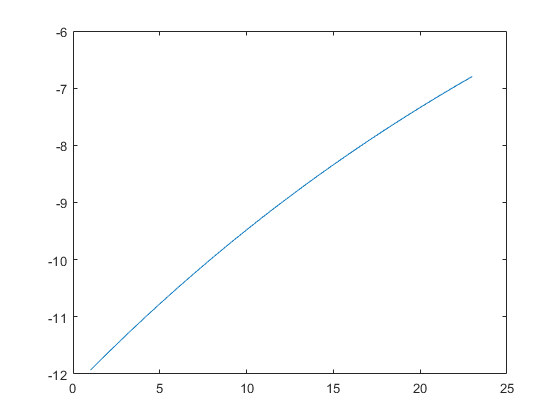

plot(t,x)

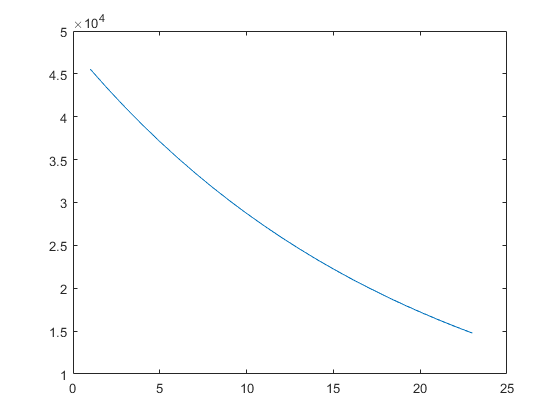

plot(t,v)

%8 kinematic viscosity v temperature
v_obs = [120.14 81.78 58.48 43.30];
temp = 298.15:10:328.15;
A = 0.00142;
B = 3382;

v_exp = A*exp(B./temp)

v_exp =   119.8433   82.9366   58.7392   42.4855


v_err = abs(v_exp-v_obs)*100./v_exp

v_err =     0.2476    1.3945    0.4413    1.9170


% error = +/- 0.5 uncertainity 

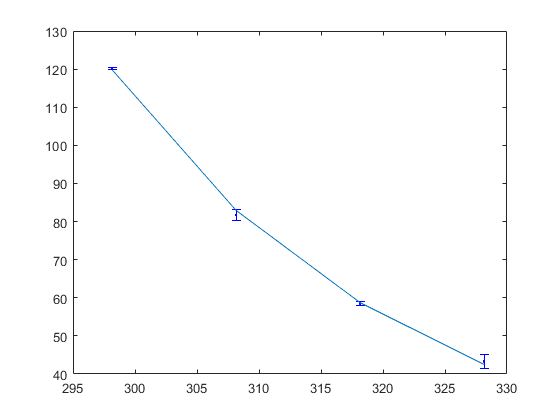

errorbar(temp, v_obs, v_err, '.b') 
hold on
plot(temp, v_exp)